## **Exercise 2, week 2 (Flow System Modelling)**

Consider a continuous flow system consisting of 6 equal compartments in series with backflow. The backflow ratio is f=0.1f = 0.1f=0.1 for all compartments, except between compartments 1 and 2, where f=0.3f = 0.3f=0.3. The average residence time has been normalized to 1.

**Tasks**:

- **a.** Use a simulation to compute the residence time distribution.

- **b.** Compare the result with the case without backflow. Is the backflow response showing a certain skewness? Explain your answer.

- **c.** Compute the central moments $\mu_1$�, $\mu_2$�, and $\mu_3$� for both models.

- **d.** Compute the flow rate matrix as part of a state-space representation for the case with backflow (refer to Section 2.3 of the lecture notes). Show that the flow rate matrix is positive definite and demonstrate stability of the flow system, for example, by computing the eigenvalues of the flow rate matrix.

close all
clear
clc

% Given parameters
f = 0.1;   % Backflow ratio
v = 1;     % Volume, assuming L/v = 1
N = 6;     % Number of compartments = 6
L = 1;     % Length, assuming L/v = 1

% Calculate α, β, and γ according to lecture notes page 59
alpha = (1 + f) * v * N / L;
beta = (1 + 2 * f) * v * N / L;
gamma = f * v * N / L;

% Display the results
disp(['α = ', num2str(alpha)]);

α = 6.6


disp(['β = ', num2str(beta)]);

β = 7.2


disp(['γ = ', num2str(gamma)]);

γ = 0.6


Reffering to the formula to model N compartments with backflow we have (sections 2.3.2): 


$$\[
\frac{d}{dt} c_k(t) = \frac{(1 + f) v N}{L} c_{k-1}(t) + \frac{f v N}{L} c_{k+1}(t) - \frac{(1 + 2f) v N}{L} c_k(t)
\]$$


In order to model this in Simlulink, we use the State Space block. We know that the state space form looks like this: 


$$\[
\dot{x}(t) = A x(t) + B u(t)
\]

\[
y(t) = C x(t) + D u(t)
\]$$


Again using the lecture notes we can define turn the equasion in 2.3.2 into state space form: 

 (just see lecture notes, my latex code is not working for some reason)

Now we can define A, B, C and D like this:

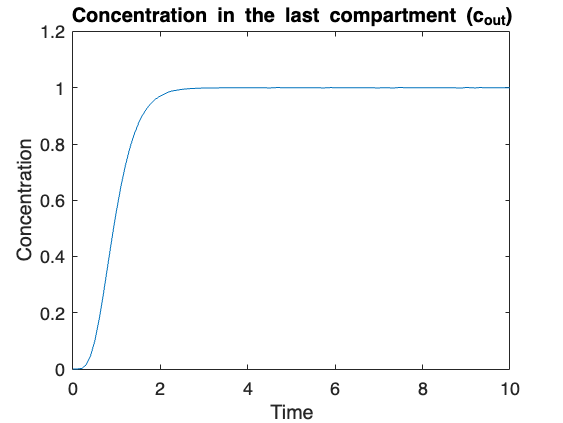

A = [

    -alpha, gamma, 0, 0, 0, 0;
    alpha, -beta, gamma, 0, 0, 0;
    0, alpha, -beta, gamma, 0, 0;
    0, 0, alpha, -beta, gamma, 0;
    0, 0, 0, alpha, -beta, gamma;
    0, 0, 0, 0, alpha, -alpha
];

B = [
    alpha - gamma;
    0;
    0;
    0;
    0;
    0
];

C = [0, 0, 0, 0, 0, 1]; 
D = 0;

We use simlunk to model 6 compartments and use the results to plot the residence time 

% Run the simulation
sim('exercise2_model')

% Plot residence time distribution
figure;
plot(simout.time, simout.signals.values);  % Assuming simout is your output variable
title('Residence Time Distribution');
xlabel('Time (s)');
ylabel('Concentration');